# Actividad 5.2: Control de Posición

- **Daniel Castillo López A01737357**

- **Emmanuel Lechuga Arreola A01736241**

- **Paola Rojas Domínguez A01737136**

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear
close all
clc

## Gato

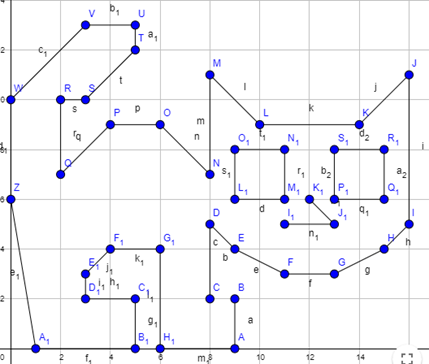

### Control en lazo abiertoclear

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 85 ;             % Tiempo de simulacion en segundos (s) 
ts = 0.2;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 1;    % Posicion inicial eje x   
y1(1) = 0;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(2, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(2, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%   0*ones(1,6)  ,,   pi/2*ones(1,6)

%zigzag 
u =[ 2*ones(1,5)   0*ones(1,5) 1*ones(1,5) 0*ones(1,5) 1*ones(1,5)    0*ones(1,5)    1*ones(1,5)    0*ones(1,5)   1*ones(1,5)  0*ones(1,5)  1*ones(1,5) 0*ones(1,5)  3*ones(1,5) 0*ones(1,5)      2*ones(1,5)    0*ones(1,5)    1*ones(1,5)  0*ones(1,5)   1*ones(1,5) 0*ones(1,5) 2*ones(1,5)...
     0*ones(1,5)   1*ones(1,5)  1*ones(1,5)  0*ones(1,5)    1*ones(1,5)    0*ones(1,5)  1*ones(1,5)  1*ones(1,5)  0*ones(1,5)    1*ones(1,5)  0*ones(1,5)   1*ones(1,5)      0*ones(1,5)       0*ones(1,5)   1*ones(1,5)  0*ones(1,5)  1*ones(1,5)     0*ones(1,5)  1*ones(1,5)  0*ones(1,5) 1*ones(1,5) 0*ones(1,5) 1*ones(1,5)...
     0*ones(1,5) 2.35*ones(1,5) 0*ones(1,5) 1*ones(1,5) 0*ones(1,5) 0*ones(1,5)     1*ones(1,5)  0*ones(1,5)    4*ones(1,5)  0*ones(1,5)     1.5*ones(1,5) 0*ones(1,5) 1.8*ones(1,5) 0*ones(1,5) 1.5*ones(1,5) 0*ones(1,5) 3*ones(1,5) 0*ones(1,5) 1.5*ones(1,5) 0*ones(1,5) 1.5*ones(1,5) 0*ones(1,5) 2*ones(1,5) 0*ones(1,5) 2*ones(1,5) 0*ones(1,5)... 
     1*ones(1,5) 0*ones(1,5) 2*ones(1,5) 0*ones(1,5) .5*ones(1,5)  0*ones(1,5) 1.5*ones(1,5) 0*ones(1,5)  2.5*ones(1,5) 0*ones(1,5) 0*ones(1,5) 3*ones(1,5)  0*ones(1,5) 3.5 *ones(1,5) 0*ones(1,6) ];

w =[ 0*ones(1,5) pi/2*ones(1,5) 0*ones(1,5) pi/2*ones(1,5) 0*ones(1,5) -pi/2*ones(1,5)   0*ones(1,5)  -0.78*ones(1,5) 0*ones(1,5) -0.78*ones(1,5) 0*ones(1,5) -pi/2*ones(1,5) 0*ones(1,5) pi/2*ones(1,5) 0*ones(1,5) pi/2*ones(1,5) 0*ones(1,5) pi/2*ones(1,5) 0*ones(1,5)  -pi/2*ones(1,5) 0*ones(1,5)...
  -2.35*ones(1,5) 0*ones(1,5) 0*ones(1,5) 0.78*ones(1,5) 0*ones(1,5)  0.78*ones(1,5)  0*ones(1,5)    0*ones(1,5)  pi/2*ones(1,5) 0*ones(1,5)  pi/4*ones(1,5)  0*ones(1,5)   0*ones(1,5)  pi/4*ones(1,5) 0*ones(1,5) 3*pi/4*ones(1,5) 0*ones(1,5)   3*pi/4*ones(1,5) 0*ones(1,5) pi/4*ones(1,5) 0*ones(1,5) -pi/2*ones(1,5) 0*ones(1,5)...
  -pi/2*ones(1,5) 0*ones(1,5) -pi/2*ones(1,5) 0*ones(1,5) 0*ones(1,5) pi/4*ones(1,5) 0*ones(1,5) 3*pi/4*ones(1,5) 0*ones(1,5) 3*pi/4*ones(1,5) 0*ones(1,5) -pi/4*ones(1,5) 0*ones(1,5) -pi/4*ones(1,5) 0*ones(1,5) 3*pi/4*ones(1,5) 0*ones(1,5) -3*pi/4*ones(1,5) 0*ones(1,5) pi/4*ones(1,5) 0*ones(1,5) pi/4*ones(1,5) 0*ones(1,5) -3*pi/4*ones(1,5) 0*ones(1,5) -pi/2*ones(1,5)...
   0*ones(1,5) pi/4*ones(1,5) 0*ones(1,5) pi/4*ones(1,5) 0*ones(1,5) pi/2*ones(1,5) 0*ones(1,5) pi/4*ones(1,5) 0*ones(1,5) 0*ones(1,5) pi/4*ones(1,5) 0*ones(1,5) 0.4*ones(1,5) 0*ones(1,5) 0*ones(1,6)];


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

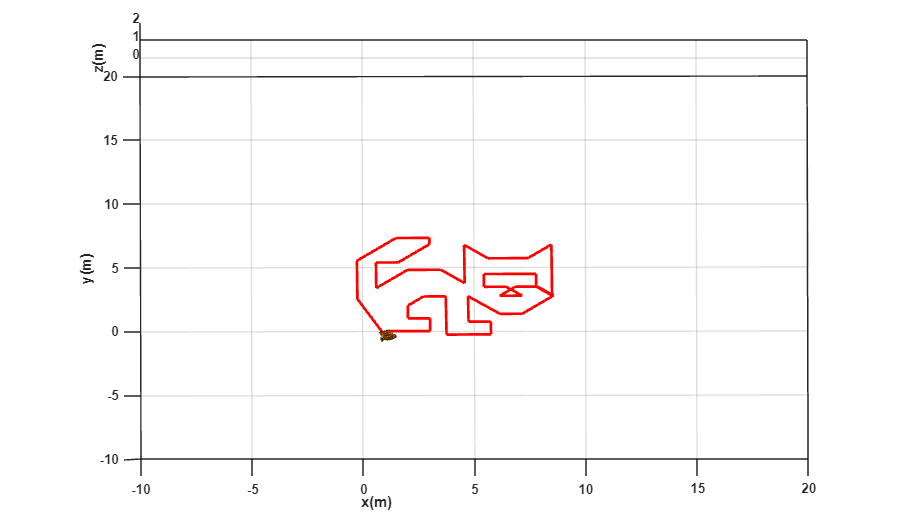

view([-0.1 35]); % Orientacion de la figura
axis([-10 20 -10 20 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

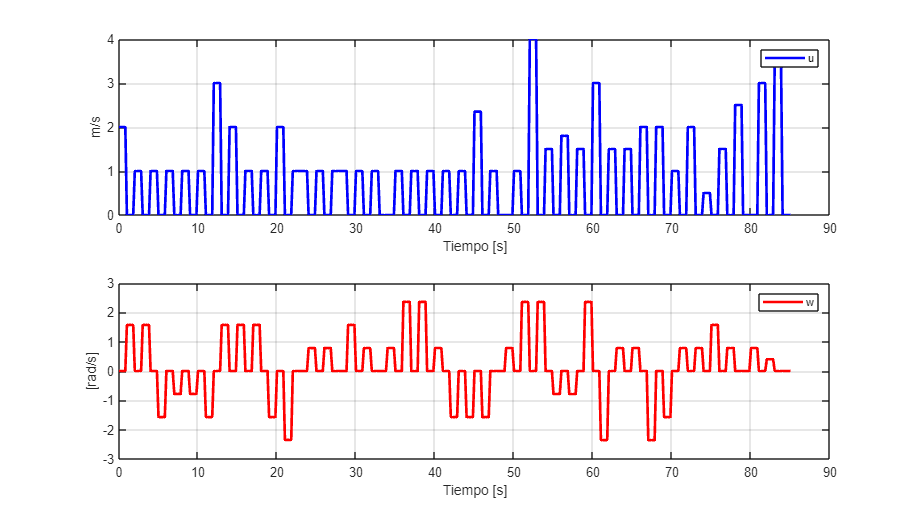


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

### Control en lazo cerrado

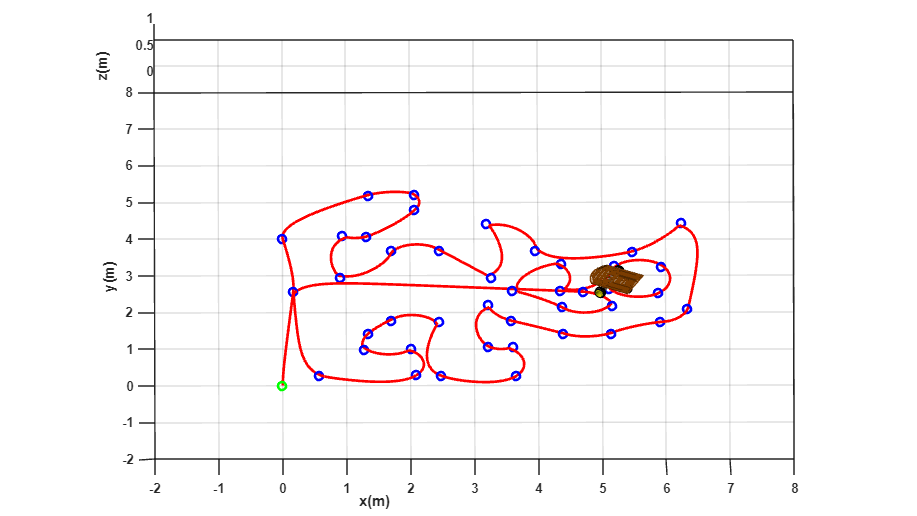

%Control lazo cerrado con seguimiento de múltiples puntos

% Limpieza de pantalla
clear all
close all
clc

% 1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 300;            % Tiempo de simulación en segundos
ts = 0.1;            % Tiempo de muestreo en segundos
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Muestras

% 2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1(1) = 0;           % Posición inicial eje x
y1(1) = 0;           % Posición inicial eje y
phi(1) = pi/2;       % Orientación inicial del robot 

% 3 PUNTOS DESEADOS A SEGUIR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
trayectoria = [
    0.1683  2.5729;
    0       4;
    1.3440  5.1883;
    2.0639  5.2123;
    2.0639  4.8044;
    1.3200  4.0606;
    0.9361  4.0846;
    0.9121  2.9328;
    1.7040  3.6766;
    2.4478  3.6766;
    3.2636  2.9328;
    3.1916  4.4205;
    3.9595  3.6766;
    5.4711  3.6527;
    6.2390  4.4205;
    6.3349  2.0930;
    5.9030  1.7331;
    5.1352  1.4212;
    4.3914  1.4212;
    3.5755  1.7571;
    3.2156  2.2130;
    3.2156  1.0612;
    3.5995  1.0612;
    3.6475  0.2694;
    2.4718  0.2694;
    2.4478  1.7331;
    1.7040  1.7811;
    1.3440  1.4212;
    1.2721  0.9892;
    2.0159  1.0132;
    2.0879  0.2934;
    0.5762  0.2694;
    0.1683  2.5729;
    4.7033  2.5489;
    5.1592  2.1650;
    4.3674  2.1410;
    3.5995  2.5729;
    4.3674  3.3167;
    4.3434  2.5729;
    5.1832  3.2687;
    5.9270  3.2447;
    5.8790  2.5249;
    5.1112  2.6449;
];

num_puntos = size(trayectoria, 1);
index_punto = 1;

% Posición del punto de control
hx(1) = x1(1);
hy(1) = y1(1);

% 4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N 

    % Punto objetivo actual
    hxd = trayectoria(index_punto, 1);
    hyd = trayectoria(index_punto, 2);

    % a)Errores de control
    dx = hxd - x1(k);
    dy = hyd - y1(k);
    dist_error = sqrt(dx^2 + dy^2);

    % b) Ángulo deseado hacia el punto objetivo
    ang_deseado = atan2(dy, dx);

    % c) Error angular (ajustado a -pi, pi)
    e_ang = ang_deseado - phi(k);
    e_ang = atan2(sin(e_ang), cos(e_ang));

    % d) Control proporcional
    Kp_v = 1.5;     
    Kp_w = 2.5;     

    % Movimiento condicionado a orientación
    if abs(e_ang) > pi/3
        v(k) = 0;
    else
        v(k) = Kp_v * dist_error * max(cos(e_ang), 0);
    end

    w(k) = Kp_w * e_ang;

    % e) Saturación de velocidades
    v(k) = max(min(v(k), 0.8), -0.8);
    w(k) = max(min(w(k), 2), -2);

    % f) Aplicación del control al modelo del robot
    phi(k+1) = phi(k) + w(k)*ts;
    x1(k+1) = x1(k) + v(k)*cos(phi(k))*ts;
    y1(k+1) = y1(k) + v(k)*sin(phi(k))*ts;

    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);

    % g) Cambio de punto objetivo
    if dist_error < 0.10 && index_punto < num_puntos
        index_punto = index_punto + 1;
    end

    Error(k) = dist_error;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 35]);
axis([-2 8 -2 8 0 1]);

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

% Graficar trayectorias
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);
H3 = plot3(trayectoria(:,1), trayectoria(:,2), zeros(num_puntos,1), 'bo', 'lineWidth', 2);
H4 = plot3(hx(1), hy(1), 0, 'go', 'lineWidth', 2);
step = 1;
for k = 1:step:N
    delete(H1);    
    delete(H2);
    
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    
    pause(ts);
end

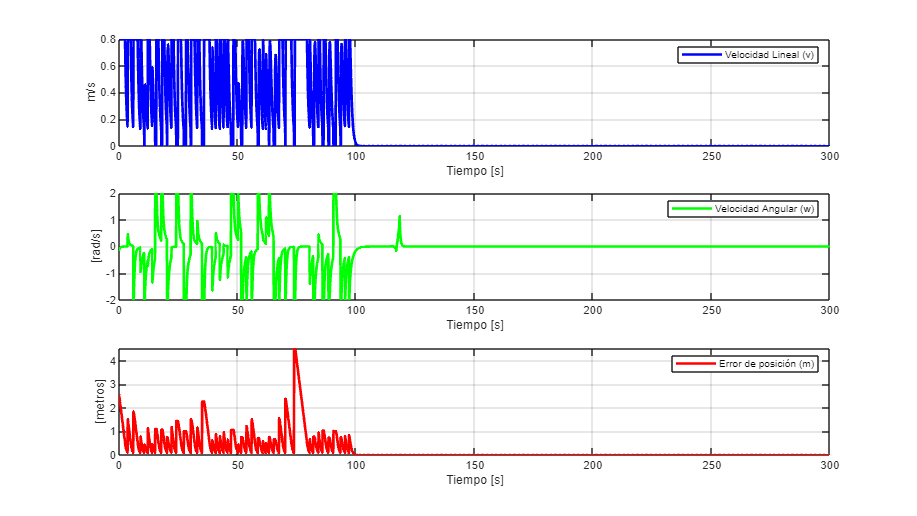


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph,'position',sizeScreen);
subplot(311)
plot(t, v, 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('m/s'), legend('Velocidad Lineal (v)');
subplot(312)
plot(t, w, 'g', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('Velocidad Angular (w)');
subplot(313)
plot(t, Error, 'r', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('[metros]'), legend('Error de posición (m)');

## Murciélago

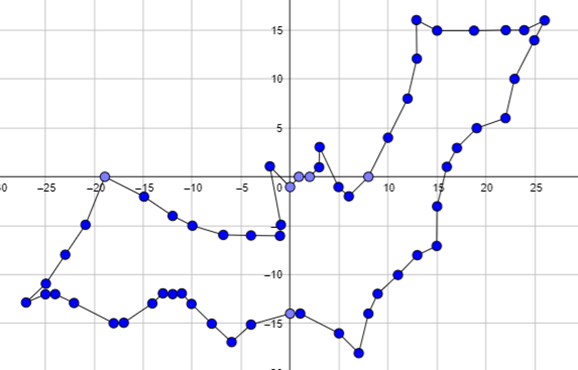

### Control en lazo abierto

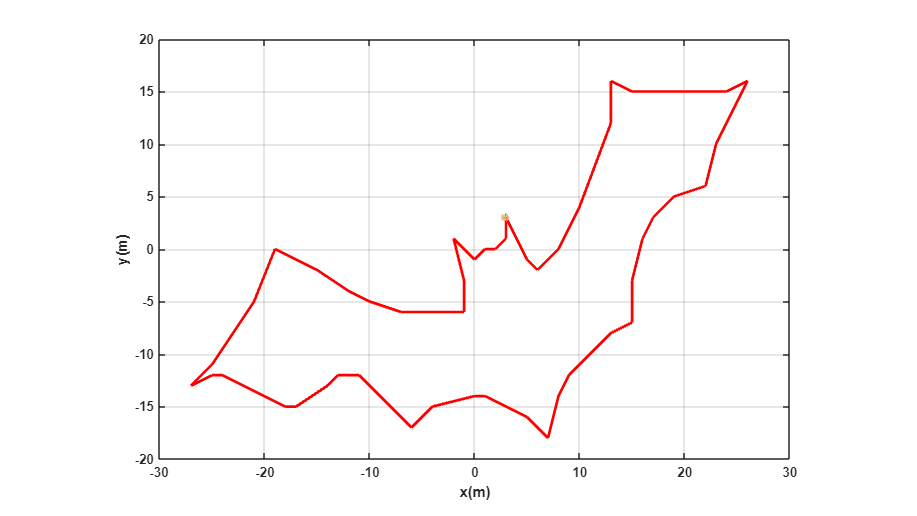

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u =[zeros(1, 10), 4.47*ones(1,10),  zeros(1, 10), 1.41*ones(1,10) , zeros(1, 10), 2.83*ones(1,10), ...
    zeros(1, 10), 4.47*ones(1,10),  zeros(1, 10), 8.54*ones(1,10) , zeros(1, 10), 4.00*ones(1,10), ...
    zeros(1, 10), 2.24*ones(1,10),  zeros(1, 10), 4.00*ones(1,10) , zeros(1, 10), 3.00*ones(1,10), ...
    zeros(1, 10), 2.00*ones(1,10),  zeros(1, 10), 2.24*ones(1,10) , zeros(1, 10), 2.24*ones(1,10), ...
    zeros(1, 10), 4.47*ones(1,10),...
    zeros(1, 10), 4.12*ones(1,10),  zeros(1, 10), 3.16*ones(1,10) , zeros(1, 10), 2.83*ones(1,10),...
    zeros(1, 10), 2.24*ones(1,10),  zeros(1, 10), 4.12*ones(1,10) , zeros(1, 10), 4.00*ones(1,10),...
    zeros(1, 10), 2.24*ones(1,10),  zeros(1, 10), 2.83*ones(1,10) , zeros(1, 10), 2.83*ones(1,10),...
    zeros(1, 10), 2.24*ones(1,10),  zeros(1, 10), 4.12*ones(1,10) , zeros(1, 10), 2.83*ones(1,10),... %Punto medio
    zeros(1, 10), 4.47*ones(1,10),  zeros(1, 10), 1.00*ones(1,10) , zeros(1, 10), 4.12*ones(1,10),...
    zeros(1, 10), 2.83*ones(1,10),  zeros(1, 10), 2.83*ones(1,10) , zeros(1, 10), 2.83*ones(1,10),...
    zeros(1, 10), 1.41*ones(1,10),  zeros(1, 10), 1.00*ones(1,10) , zeros(1, 10), 1.00*ones(1,10),...
    zeros(1, 10), 1.41*ones(1,10),  zeros(1, 10), 3.61*ones(1,10) , zeros(1, 10), 1.00*ones(1,10),...
    zeros(1, 10), 4.47*ones(1,10),  zeros(1, 10), 2.24*ones(1,10) , zeros(1, 10), 1.00*ones(1,10),...% Seccion 2
    zeros(1, 10), 2.24*ones(1,10),  zeros(1, 10), 2.83*ones(1,10) , zeros(1, 10), 3.61*ones(1,10),...
    zeros(1, 10), 3.61*ones(1,10),  zeros(1, 10), 5.39*ones(1,10) , zeros(1, 10), 4.47*ones(1,10),...
    zeros(1, 10), 3.61*ones(1,10),  zeros(1, 10), 2.24*ones(1,10) , zeros(1, 10), 3.16*ones(1,10),...
    zeros(1, 10), 3.00*ones(1,10),  zeros(1, 10), 3.00*ones(1,10) , zeros(1, 10), 3.00*ones(1,10),...
    zeros(1, 10), 4.12*ones(1,10),  zeros(1, 10), 2.83*ones(1,10) , zeros(1, 10), 1.41*ones(1,10),...
    zeros(1, 10), 1.00*ones(1,10),  zeros(1, 10), 1.41*ones(1,10) , zeros(1, 10), 2.00*ones(1,10),...
    zeros(1, 10), zeros(1, 10)];


w =[deg2rad(-63.43).*ones(1, 10),   zeros(1,10), deg2rad(18.43).*ones(1, 10),   zeros(1,10),...
    deg2rad(90).*ones(1, 10),       zeros(1,10), deg2rad(18.43).*ones(1, 10),   zeros(1,10), deg2rad(6.01).*ones(1, 10),    zeros(1,10),... 
    deg2rad(20.56).*ones(1, 10),    zeros(1,10), deg2rad(-116.57).*ones(1, 10), zeros(1,10), deg2rad(26.57).*ones(1, 10),   zeros(1,10),... 
    deg2rad(0).*ones(1, 10),        zeros(1,10), deg2rad(0).*ones(1, 10),       zeros(1,10), deg2rad(26.57).*ones(1, 10),   zeros(1,10),... 
    deg2rad(-143.13).*ones(1, 10),  zeros(1,10), deg2rad(0).*ones(1, 10),       zeros(1,10), ...                                             
    deg2rad(12.53).*ones(1, 10),    zeros(1,10), deg2rad(-57.53).*ones(1, 10),  zeros(1,10), deg2rad(26.57).*ones(1, 10),   zeros(1,10),... 
    deg2rad(18.43).*ones(1, 10),    zeros(1,10), deg2rad(12.53).*ones(1, 10),   zeros(1,10), deg2rad(14.04).*ones(1, 10),   zeros(1,10),... 
    deg2rad(-63.43).*ones(1, 10),   zeros(1,10), deg2rad(18.43).*ones(1, 10),   zeros(1,10), deg2rad(0).*ones(1, 10),       zeros(1,10),... 
    deg2rad(18.43).*ones(1, 10),    zeros(1,10), deg2rad(12.53).*ones(1, 10),   zeros(1,10), deg2rad(-120.96).*ones(1, 10), zeros(1,10),... %Punto medio
    deg2rad(18.43).*ones(1, 10),    zeros(1,10), deg2rad(26.57).*ones(1, 10),   zeros(1,10),...                                            
    deg2rad(14.04).*ones(1, 10),    zeros(1,10), deg2rad(30.96).*ones(1, 10),   zeros(1,10), deg2rad(-90.0).*ones(1, 10),   zeros(1,10),...
    deg2rad(0.00).*ones(1, 10),     zeros(1,10), deg2rad(0.00).*ones(1, 10),    zeros(1,10), deg2rad(45.00).*ones(1, 10),   zeros(1,10),... 
    deg2rad(0.00).*ones(1, 10),     zeros(1,10), deg2rad(45.0).*ones(1, 10),    zeros(1,10), deg2rad(-11.31).*ones(1, 10),  zeros(1,10),... 
    deg2rad(-33.69).*ones(1, 10),   zeros(1,10), deg2rad(-26.57).*ones(1, 10),  zeros(1,10), deg2rad(00.00).*ones(1, 10),   zeros(1,10),... 
    deg2rad(26.57).*ones(1, 10),    zeros(1,10), deg2rad(26.57).*ones(1, 10),   zeros(1,10), deg2rad(-161.57).*ones(1, 10), zeros(1,10),...%seccion 3 
    deg2rad(11.31).*ones(1, 10),    zeros(1,10), deg2rad(0).*ones(1, 10),       zeros(1,10), deg2rad(11.89).*ones(1, 10),   zeros(1,10),...
    deg2rad(-94.76).*ones(1, 10),   zeros(1,10), deg2rad(-7.13).*ones(1, 10),   zeros(1,10), deg2rad(7.13).*ones(1, 10),    zeros(1,10),...
    deg2rad(8.13).*ones(1, 10),     zeros(1,10), deg2rad(18.43).*ones(1, 10),   zeros(1,10), deg2rad(00.00).*ones(1, 10),   zeros(1,10),...
    deg2rad(90).*ones(1, 10),       zeros(1,10), deg2rad(14.04).*ones(1, 10),   zeros(1,10), deg2rad(-149.04).*ones(1, 10), zeros(1,10),...
    deg2rad(90).*ones(1, 10),       zeros(1,10), deg2rad(-45).*ones(1, 10),     zeros(1,10), deg2rad(45.00).*ones(1, 10),   zeros(1,10),...
    deg2rad(45.00).*ones(1, 10),    zeros(1,10), deg2rad(-90.00).*ones(1, 10),  zeros(1,10)];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

N = length(u);       % Muestras
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = linspace(0, ts, N);  % Vector de tiempo



%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posici n en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posici n en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 3;    % Posicion inicial eje x
y1(1) = 3;    % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral num rica (m todo de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    %Poses
    x1(k+1)=x1(k) + xp1*ts ; % Integral num rica (m todo de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral num rica (m todo de Euler)
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%% 

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tama o de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tama o de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relaci n de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar l neas de cuadr cula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([0 90]); % Orientacion de la figura
axis([-30 30 -20 20 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

### Control en lazo cerrado

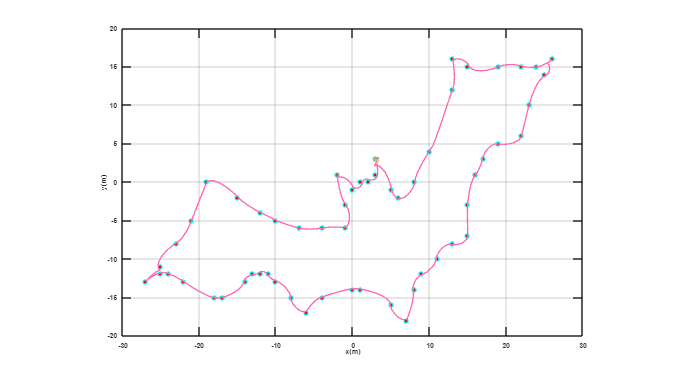

x1(1) = 3; 
y1(1) = 3;
phi(1) = pi/2;
hx(1) = x1(1);
hy(1) = y1(1);

coord = [  3,  3;   5, -1;   6, -2;   8,  0;  10,  4;  13, 12;
                13, 16;  15, 15; 19, 15; 22, 15; 24, 15; 26, 16;
                25, 14;  23, 10; 22, 6; 19, 5; 17 ,3; 16,  1;
                15, -3; 15, -7; 13, -8;  11, -10; 9, -12;  8, -14;
                7, -18;   5, -16; 1, -14;  0, -14; -4, -15; -6, -17;
               -8, -15; -10, -13; -11, -12; -12, -12; -13, -12; -14, -13;
               -17, -15; -18, -15; -22, -13; -24, -12; -25, -12; -27, -13;
               -25, -11;  -23, -8; -21, -5; -19, 0; -15, -2; -12, -4;
                -10, -5;  -7, -6; -4, -6; -1, -6; -1, -3; -2, 1;
                0, -1;    1,  0;   2,  0;   3,  1;   3,  3];
ts = 0.1;
tf = 15;
N = tf / ts;
t = linspace(0, ts, N);

scale = 4;
sizeScreen = get(0,'ScreenSize');
scene = figure('Name','Animación trayectoria completa');
set(scene, 'Color','white', 'position', sizeScreen);
set(gca,'FontWeight','bold');
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([0 90]); % Orientación de la figura
axis([-30 30 -20 20 0 1]); % Límites de los ejes

% Mostrar los puntos deseados
hold on;
plot(coord(:,1), coord(:,2), 'ro', 'MarkerFaceColor', 'r'); % Puntos de destino

% Inicializar trazado
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2);
plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2); % punto inicial


% Inicialización para cada segmento
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

for i = 1:size(coord,1)
    hxd = coord(i,1);
    hyd = coord(i,2);

    for k = 1:N
        
        hxe = hxd - hx(end);
        hye = hyd - hy(end);
        he = [hxe; hye];
        Error(k) = norm(he);
        
        J = [cos(phi(end)) -sin(phi(end)); sin(phi(end)) cos(phi(end))];

        Kp_base = 0.1;
        Kp_max = 1;
        Error_max = 2.0;
        error_norm = norm(he);
        Kp_k = Kp_base + (Kp_max - Kp_base) * tanh(error_norm/Error_max);
        K = Kp_k * eye(2);
        
        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);
        
        % Actualizar estado
        phi(end+1) = phi(end) + w(k)*ts;
        xp1 = v(k)*cos(phi(end-1));
        yp1 = v(k)*sin(phi(end-1));
        x1(end+1) = x1(end) + xp1*ts;
        y1(end+1) = y1(end) + yp1*ts;
        hx(end+1) = x1(end);
        hy(end+1) = y1(end);
    end

    % Actualizar animación del movimiento
    step = 5;  
    for k = length(hx)-N+1:step:length(hx)
        delete(H1);
        delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'Color', [1 0.4 0.7], 'LineWidth', 2);
        plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % punto objetivo
        pause(ts);
    end
end

## Mariposa

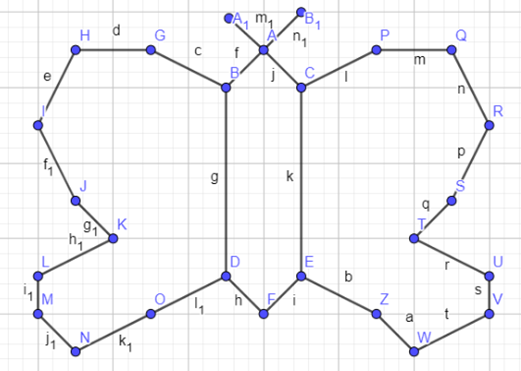

### Control en lazo abierto

#### Velocidades de referencia

Se comienza definiendo los vectores de referencia de velocidad.  Esta secuencia está pensada para simular un movimiento cuadrado en el plano.

u = [zeros(1, 10), 1.25*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 5*ones(1, 10), zeros(1, 10), 5*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.24*ones(1, 10), zeros(1, 10), 5*ones(1, 10), zeros(1, 10), 5*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10), zeros(1, 10), 1.41*ones(1, 10)];
w = [deg2rad(-42.4)*ones(1, 10), zeros(1, 10), deg2rad(-2.6)*ones(1, 10), zeros(1, 10), deg2rad(71.57)*ones(1, 10), zeros(1, 10), deg2rad(-26.57)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(-53.43)*ones(1, 10), zeros(1, 10), deg2rad(-18.43)*ones(1, 10), zeros(1, 10), deg2rad(108.43)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(-71.57)*ones(1, 10), zeros(1, 10), deg2rad(18.43)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(180)*ones(1, 10), zeros(1, 10), deg2rad(-45)*ones(1, 10), zeros(1, 10), deg2rad(-90)*ones(1, 10), zeros(1, 10), deg2rad(71.57)*ones(1, 10), zeros(1, 10), 0*ones(1, 10), zeros(1, 10), deg2rad(-71.57)*ones(1, 10), zeros(1, 10), deg2rad(-45)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(108.43)*ones(1, 10), zeros(1, 10), deg2rad(-18.43)*ones(1, 10), zeros(1, 10), deg2rad(-53.13)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(-26.57)*ones(1, 10), zeros(1, 10), deg2rad(-63.43)*ones(1, 10), zeros(1, 10), deg2rad(180)*ones(1, 10), zeros(1, 10), deg2rad(-45)*ones(1, 10), zeros(1, 10), 0*ones(1, 10), zeros(1, 10)];

#### Tiempo

A continuación, se establecen los parámetros temporales. El número de muestras `N` se obtiene a partir de la longitud del vector `u`, mientras que el tiempo de muestreo se define como `ts = 0.1` segundos. El vector de tiempo `t` se genera con una distribución lineal.

N = length(u);
tf = N*2;
ts = 0.1;
t = linspace(0, ts, N);

#### Condiciones iniciales

Las condiciones iniciales del robot se fijan en el origen del plano, con orientación cero. Los vectores `x1`, `y1` y `phi` representan respectivamente la posición en el eje X, el eje Y y la orientación del robot a lo largo de toda la simulación.

x1 = zeros (1,N+1);
y1 = zeros (1,N+1);
phi = zeros(1, N+1);

Se establece la coordenada inicial, asignando los valores explícitamente en la primera posición de cada vector. 

x1(1) = 7.08;
y1(1) = 9.84;
phi(1) = 0;

#### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx = zeros(1, N+1);
hy = zeros(1, N+1);

hx(1) = x1(1);
hy(1) = y1(1);

#### Bucle de simulación

El bucle `for` que recorre todas las muestras temporales. En cada iteración, se actualiza la orientación `phi` del robot utilizando integración numérica con el método de Euler. Luego, se calculan las componentes de la velocidad en los ejes X y Y considerando la orientación recién calculada. Con esas velocidades, también mediante Euler, se actualiza la posición del robot. Finalmente, se actualiza la trayectoria del punto de control con las nuevas coordenadas del centro del robot.

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

#### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

**a) Configuracion de escena**

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([0 15 0 15 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar Trayectorias**

H2=plot3(hx(1),hy(1),0,'c','lineWidth',2);

**d) Bucle de simulacion de movimiento del robot**

Se dibuja el robot en su posición inicial mediante una función externa (`MobilePlot_4`) que toma como parámetros la posición, orientación y una escala de visualización. Luego, se dibuja la primera parte de la trayectoria del punto de control en color rojo. El bucle de simulación gráfica recorre los pasos definidos, actualizando la posición del robot y su trayectoria en cada iteración.

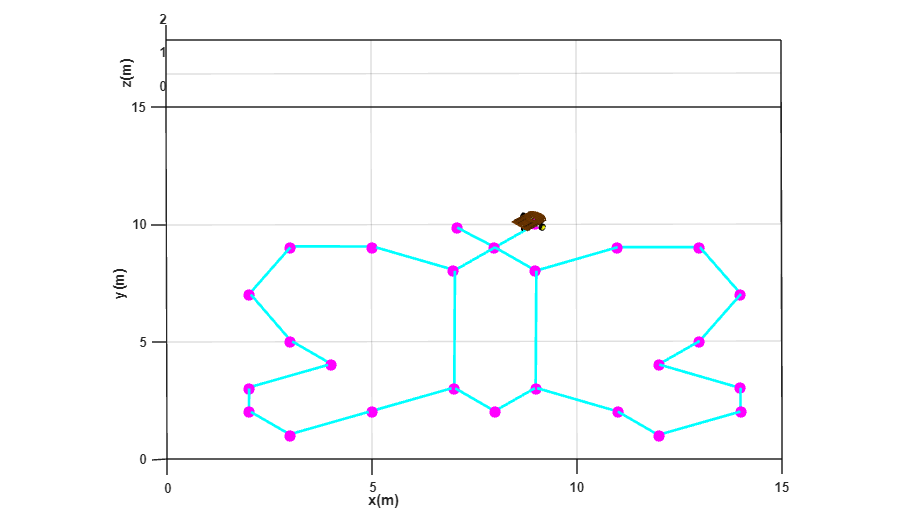

puntosX = [7.08, 8, 9, 11, 13, 14, 13, 12, 14, 14, 12, 11, 9, 9, 7, 7, 8, 5, 3, 2, 3, 4, 2, 2, 3, 5,  9]; 
puntosY = [9.84, 9, 8,  9,  9,  7,  5,  4,  3,  2,  1,  2, 3, 8, 8, 3, 2, 9, 9, 7, 5, 4, 3, 2, 1, 2, 10];

% Dibujar puntos fijos en la escena
plot3(puntosX, puntosY, zeros(size(puntosX)), 'mo', 'MarkerSize', 8, 'MarkerFaceColor', 'm');

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'c','lineWidth',2);
    
    pause(ts);

end

#### Gráficas

Finalmente, se muestran las gráficas de las velocidades `u` y `w` a lo largo del tiempo. Se usan subplots para presentar ambas curvas por separado, manteniendo una línea clara y visible. Estas gráficas permiten verificar que las referencias de velocidad se aplicaron correctamente a lo largo de la simulación.

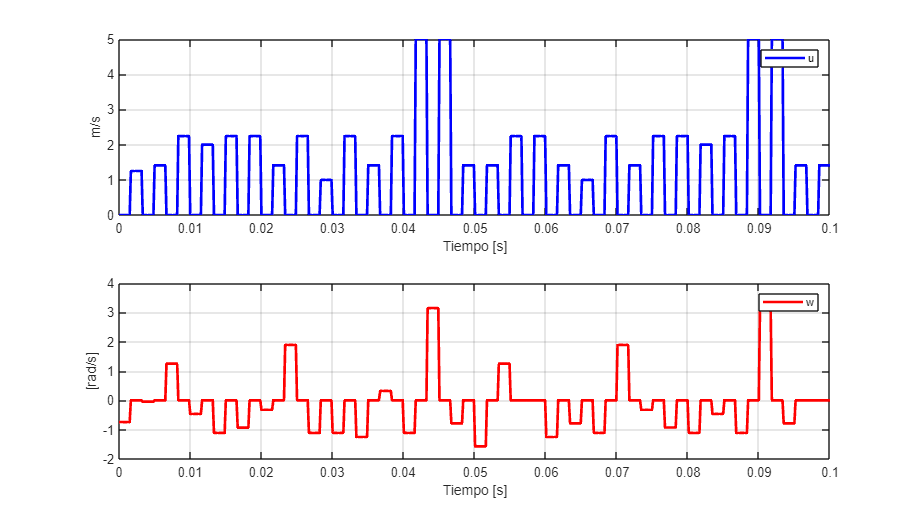

graph=figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

### Control en lazo cerrado

#### Tiempo

A continuación, se establecen los parámetros temporales

ts = 0.1;
t_segmento = 15;
N = t_segmento / ts;
t = linspace(0, ts, N);

#### Lista de puntos deseados

Se establece una matriz con las coordenadas a las cuales se desea que llegue el robot

puntos_deseados = [8,    9;
                   9,    8;
                  11,    9;
                  13,    9;
                  14,    7;
                  13,    5;
                  12,    4;
                  14,    3;
                  14,    2;
                  12,    1;
                  11,    2;
                   9,    3;
                   9,    8;
                   9,    3;
                   8,    2;
                   7,    3;
                   5,    2;
                   3,    1;
                   2,    2;
                   2,    3;
                   4,    4;
                   3,    5;
                   2,    7;
                   3,    9;
                   5,    9;
                   7,    8;
                   7,    3;
                   7,    8;
                   8,    9;
                   9,   10];

#### Condiciones iniciales

Se establece la coordenada inicial, asignando los valores explícitamente en la primera posición de cada vector. 

x1(1) = 7.08; 
y1(1) = 9.84;
phi(1) = pi/2;

#### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx(1) = x1(1);
hy(1) = y1(1);

scale = 4;

#### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

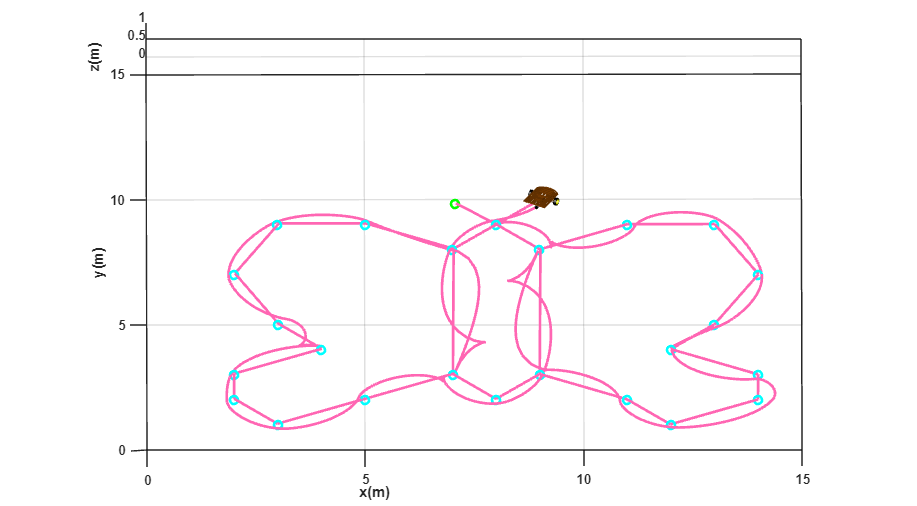

sizeScreen = get(0,'ScreenSize');
scene = figure('Name','Animación trayectoria completa');
set(scene, 'Color','white', 'position', sizeScreen);
set(gca,'FontWeight','bold');
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 35]);
axis([0 15 0 15 0 1]);

% Inicializar trazado
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2);
plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2); % punto inicial


% Inicialización para cada segmento
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

for i = 1:size(puntos_deseados,1)
    hxd = puntos_deseados(i,1);
    hyd = puntos_deseados(i,2);

    for k = 1:N
        
        hxe = hxd - hx(end);
        hye = hyd - hy(end);
        he = [hxe; hye];
        Error(k) = norm(he);
        
        J = [cos(phi(end)) -sin(phi(end)); sin(phi(end)) cos(phi(end))];

        Kp_base = 0.1;
        Kp_max = 1;
        Error_max = 2.0;
        error_norm = norm(he);
        Kp_k = Kp_base + (Kp_max - Kp_base) * tanh(error_norm/Error_max);
        K = Kp_k * eye(2);
        
        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);
        
        % Actualizar estado
        phi(end+1) = phi(end) + w(k)*ts;
        xp1 = v(k)*cos(phi(end-1));
        yp1 = v(k)*sin(phi(end-1));
        x1(end+1) = x1(end) + xp1*ts;
        y1(end+1) = y1(end) + yp1*ts;
        hx(end+1) = x1(end);
        hy(end+1) = y1(end);
    end

    % Actualizar animación del movimiento
    step = 1;
    for k = length(hx)-N+1:step:length(hx)
        delete(H1);
        delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'Color', [1 0.4 0.7], 'LineWidth', 2);
        plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % punto objetivo
        pause(ts);
    end
end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

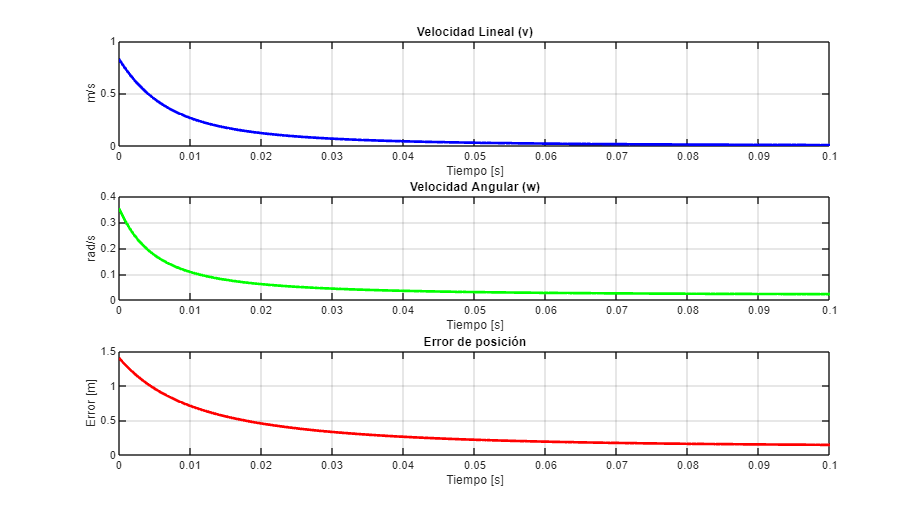

graph = figure('Name',['Gráficas punto ' char(96+i)], 'position', sizeScreen);

subplot(311)
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('m/s');
title('Velocidad Lineal (v)');

subplot(312)
plot(t, w, 'g', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('rad/s');
title('Velocidad Angular (w)');

subplot(313)
plot(t, Error, 'r', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de posición');